# SSH MODEL 

#### BAND STRUCTURE DEMO

REGIME 1: WEAKLY COUPLED DIMER: |v| << |w|

REGIME 2: STRONGLY COUPLED DIMER: |v| >> |w|

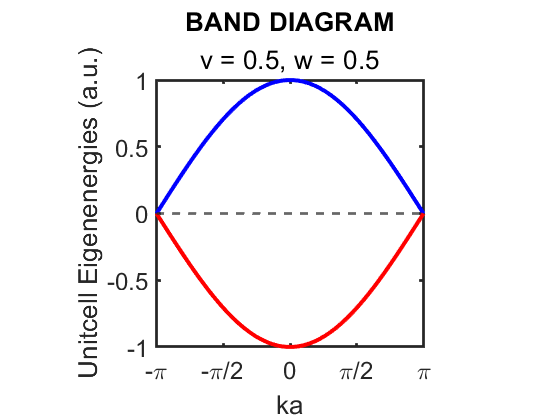

close all
clear all
omega_0 = 0;

v =0.5; % intracell coupling
w =0.5;% interell coupling

v = v ;


ka = linspace(-pi,pi,50);

omega_up = omega_0 + sqrt(v^2+w^2+2*v*w*cos(ka));
omega_dn = omega_0 - sqrt(v^2+w^2+2*v*w*cos(ka));

phi_up =  -angle(+sqrt(v^2+w^2+2*v*w*cos(ka))./(v+w*exp(-1i*(ka))));
phi_dn =  -angle(-sqrt(v^2+w^2+2*v*w*cos(ka))./(v+w*exp(-1i*(ka))));


%%% FIGURES %%%%%%%%%%%%%%%%%%%%%%%%%%%
close all
figure(1)
set(gca,'FontSize',18)
set(gca,'LineWidth',2)
box on
xlim([-pi,pi])
%ylim([-10,10])
hold on
plot(ka,omega_up,'b-','LineWidth',3)
plot(ka,omega_dn,'r-','LineWidth',3)
%yline(omega_0,'--','\omega_0','LineWidth',2,'FontSize',18)
yline(omega_0,'--','','LineWidth',2,'FontSize',18)
hold off
set(gca,'XTick',-pi:pi/2:pi)
set(gca,'XTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})
 
 
xlabel("ka")
%ylabel("Unitcell Eigenfrequencies (\omega_0)")
ylabel("Unitcell Eigenenergies (a.u.)")
%legend('\omega_{-}','\omega_{+}')
title('BAND DIAGRAM', sprintf('v = %.1f, w = %.1f',[v,w]))

axis square

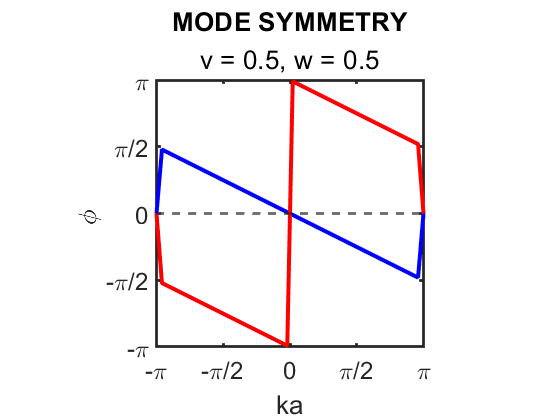


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
figure(2)
set(gca,'FontSize',18)
set(gca,'LineWidth',2)
box on
xlim([-pi,pi])
ylim([-pi,pi])
hold on
plot(ka,phi_up,'b-','LineWidth',3)
plot(ka,phi_dn,'r-','LineWidth',3)
%yline(0,'--','\omega_0','LineWidth',2,'FontSize',18)
yline(0,'--','','LineWidth',2,'FontSize',18)
hold off
set(gca,'XTick',-pi:pi/2:pi)
set(gca,'XTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})

set(gca,'YTick',-pi:pi/2:pi)
set(gca,'YTickLabel',{'-\pi','-\pi/2','0','\pi/2','\pi'})
 
xlabel("ka")
ylabel("\phi ")
%legend('\omega_{-}','\omega_{+}')
title('MODE SYMMETRY',sprintf('v = %.1f, w = %.1f',[v,w]))

axis square



%}

#### WINDING NUMBER DEMO

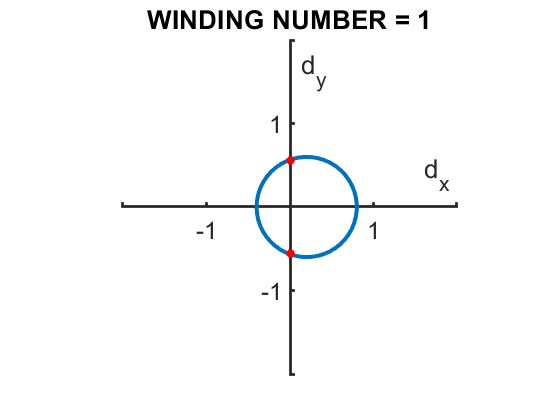

close all
v =0.2; %intracell coupling
w =0.6; %interell coupling

ka = linspace(-pi,pi,50);

dx = v + w*cos(ka) ;
dy = w*sin(ka);


zci = @(v) find(diff(sign(v))); %where cross zero
idx0 = zci(dx);

if v<w
    winding = 1;
else
    winding = 0;
end


figure(3)
hold on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.FontSize = 18  ;
ax.LineWidth = 2;

plot(dx,dy,'LineWidth',3)
plot([zeros(1,length(idx0))],(dy(idx0)+dy(idx0+1))/2,'r*','LineWidth',3)
hold off
xlim([-2,2])
ylim([-2,2])
xlabel("d_x")
ylabel("d_y")
axis square
%box on
title(sprintf('WINDING NUMBER = %i',winding))